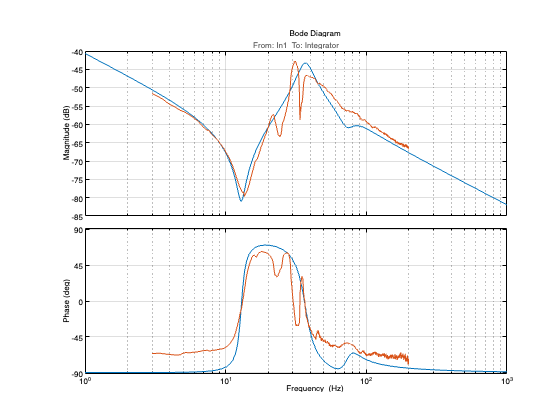

s = tf('s');


JMret=JMe+JLe/Ne^2+23;
JLret=JLe+JMe/Ne^2;

J_stareg = (JMret*JLret)/(JMret+JLret);

Kket=JLret/0.07^2*35;
Kvet=0.0017*Kket;

fix_conset = 0.0507818;

pole_at_zero = fix_conset/(s);

complex_duble_zero = 1+Kvet*s/Kket+JLret*s^2/Kket;

complex_duble_pole = 1+Kvet*s/Kket+J_stareg*s^2/Kket;

H_M = pole_at_zero*complex_duble_zero/complex_duble_pole;
elev_theco_plant=H_M;
